# **Praktikum 3 - Shift 2**

`26 September 2023`

`Nama : Tesalonika Permatasari Hutapea`

`NIM  : 10121052`

## Nomor 1

Misalkan diketahui matriks B sebagai berikut


$$B=\left\lbrack \begin{array}{ccc}
1 & 5 & 5\\
-3 & -12 & -6\\
4 & 25 & 44
\end{array}\right\rbrack$$


## Nomor 1A

Dilakukan dekomposisi LU terhadap matriks B, sehingga didapatkan hasil


$$B=\textrm{LU}=\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
-3 & 3 & 0\\
l_1  & 5 & l_2 
\end{array}\right\rbrack U$$


Bangun matriks $U$ yang sesuai!

% Ketik jawaban Anda di bawah garis
% =================================
n = 3;
A =[1,5,5;
    -3,-12,-6;
    4,25,44];


n = length(A);
L = zeros(n); % matriks 0 dan nantinya diisi matriks segitiga bawah
U = eye(n); % matriks diagonal
for i = 1:n
    for j = i:n
        sum = 0;
        for k = 1:(j-1)
            sum = sum + L(j, k) .* U(k, i);
        end
        L(j, i) = A(j, i) - sum;
    end
    for j = (i+1):n
        sum = 0;
        for k = 1:(i-1)
            sum = sum + L(i, k) .* U(k, j);
        end
        U(i, j) = (A(i, j) - sum) ./ L(i, i);
    end
end
disp(U);

     1     5     5
     0     1     3
     0     0     1



disp(L);

     1     0     0
    -3     3     0
     4     5     9



## Nomor 1B

Dengan menggunakan matriks $L$ yang seharusnya anda dapatkan pada bagian 1A, carilah matriks $L^{-1}$ menggunakan konsep Operasi Baris Elementer!

% Ketik jawaban Anda di bawah garis
% ==================================    
[baris, kolom] = size(L);

    % Periksa apakah matriks A adalah matriks persegi
if baris ~= kolom
    error('Matriks non-persegi tidak memiliki invers.');
end

    % Buat matriks identitas I dengan ukuran yang sesuai
I = eye(kolom);

    % Gabungkan matriks B dengan matriks identitas I
augmented_matrix = [L, I];

    % Tahap eliminasi
for k = 1:kolom
    m = k;
    for i = k + 1:kolom
        if abs(augmented_matrix(i, k)) > abs(augmented_matrix(m, k))
            m = i;
        end
    end
    if m ~= k
        augmented_matrix([k, m], :) = augmented_matrix([m, k], :);
    end
    if abs(augmented_matrix(k, k)) < 1e-15
        error('Matriks tidak memiliki invers.');
    end
    p = augmented_matrix(k, k);
    augmented_matrix(k, :) = augmented_matrix(k, :) / p;
    for i = 1:kolom
        if i ~= k
            p = augmented_matrix(i, k);
            augmented_matrix(i, :) = augmented_matrix(i, :) - p * augmented_matrix(k, :);
        end
    end
end


    % Mengambil invers dari hasil eliminasi
inverse = augmented_matrix(:, kolom + 1:end);
disp(inverse);

    1.0000         0         0
    1.0000    0.3333         0
   -1.0000   -0.1852    0.1111



ans =     1.0000         0         0
    1.0000    0.3333         0
   -1.0000   -0.1852    0.1111


## Nomor 1C

Buktikan bahwa matriks $U$ yang anda dapatkan pada bagian 1A benar dengan mengalikan matriks $L^{-1}$ dengan $B$!

% Ketik jawaban Anda di bawah garis
% =================================
U_new = inverse*A;
disp(U_new);

    1.0000    5.0000    5.0000
         0    1.0000    3.0000
         0         0    1.0000



## Nomor 1D

Diberikan Sistem Persamaan Linear (SPL) 


$$\textrm{Bx}=c=\left\lbrack \begin{array}{c}
0\\
1\\
3
\end{array}\right\rbrack$$


Menggunakan hasil dekomposisi yang telah Anda bangun, selesaikan SPL tersebut menggunakan metode penyulihan dan buktikan bahwa jawaban anda benar!

% Ketik jawaban Anda di bawah garis
% =================================
b = [0;1;3];

A = [L,b];
    [baris, kolom] = size(A);

    % Tahap Eliminasi Gauss hingga segitiga bawah
    for i = 1:baris
        % Pilih elemen pivot
        pivot = A(i, i);

        % Lakukan eliminasi untuk setiap baris di bawah baris pivot
        for j = i + 1:baris
            factor = A(j, i) / pivot;
            A(j, i:end) = A(j, i:end) - factor * A(i, i:end);
        end
    end

    % Penyulihan Maju
    if abs(A(1, 1)) < 1e-15
        disp('proses gagal');
        return;
    end
    x = zeros(1, kolom - 1);
    x(1) = A(1, kolom) / A(1, 1);
    for k = 2:kolom - 1
        s = 0;
        for i = 1:k - 1
            s = s + A(k, i) * x(i);
        end
        x(k) = (A(k, kolom) - s) / A(k, k);
    end
    rkpsi = transpose(x);
    h2 = [U,rkpsi];

    % pake isi fungsi untuk Upsi = y dengan penyulihan mundur
    [baris, kolom] = size(h2);

    % Tahap Eliminasi
    for k = 1:(kolom - 1)
        if abs(h2(k, k)) < 1e-15
            disp('proses gagal, sehingga Ax=B tidak memiliki solusi');
            return; % Terminate the function if the process fails
        end
        for i = (k + 1):baris
            p = h2(i, k) / h2(k, k);
            for j = (k + 1):kolom
                h2(i, j) = h2(i, j) - (p * h2(k, j));
            end
            h2(i, k) = 0;
        end
    end

    % Substitusi mundur
    if abs(h2(baris, kolom - 1)) < 1e-15
        disp('proses gagal, sehingga Ax=B tidak memiliki solusi');
        return; % menghentikan fungsi kalau gagal
    end

    psi = zeros(1, kolom - 1);
    psi(kolom - 1) = h2(baris, kolom) / h2(baris, kolom - 1);
    for k = (kolom - 2):-1:1
        s = 0;
        for i = (k + 1):(kolom - 1)
            s = s + h2(k, i) * psi(i);
        end
        psi(k) = (h2(k, kolom) - s) / h2(k, k);
    end
disp(psi);

   -0.1852   -0.1111    0.1481



## Nomor 2

Kita tahu bahwa kumpulan $n+1$ titik **tertentu **pada suatu bidang $x-y$ dapat dihubungkan oleh kurva yang dinyatakan oleh suatu polinomial

## 
$$y=f\left(x\right)=\sum_{k=0}^n a_k x^k$$


Teknik ini disebut sebagai **Interpolasi Polinom**

## Nomor 2A

Tentukan Sistem Persamaan Linear (SPL) yang terbentuk dalam mencari $\left\lbrack a_0 ,a_1 ,a_2 ,\ldotp \ldotp \ldotp ,a_n \right\rbrack$ apabila dilakukan Interpolasi Polinom pada $n+1$ buah titik $\left(x,y\right)$ sembarang! *(Catatan : Asumsikan titik-titik tersebut bisa diinterpolasikan)*

Jawab : y = $\left\lbrack \begin{array}{ccccc}
1 & x_0  & x_0^2  & \ldotp \ldotp \ldotp  & x_0^n \\
1 & x_1  & x_1^2  & \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp \\
1 & x_2  & x_2^2  & x_2^3  & \ldotp \ldotp \ldotp \\
1 & x_3  & x_3^2  & x_3^3  & \ldotp \ldotp \ldotp \\
1 & x_n  & x_n^2  & \ldotp \ldotp \ldotp  & x_n^n 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
a_0 \\
\\
\ldotp \ldotp \ldotp \\
\ldotp \ldotp \ldotp \\
\mathrm{an}
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\mathrm{y0}\\
\mathrm{y1}\\
\mathrm{y2}\\
\ldotp \ldotp \ldotp \\
\mathrm{yn}
\end{array}\right\rbrack$

## Nomor 2B

Menurut anda, sesuai dengan asumsi yang diberikan, apakah SPL tersebut selalu memiliki solusi? Berapa banyak solusi yang dimiliki? Jelaskan!

Jawab : Terdapat beberapa kasus yang memungkinkan. 

- Solusi banyak apabila terdapat baris 0 pada matriks augmented [X | b] atau terdapat lebih banyak variabel daripada persamaan.

- Tidak punya solusi apabila terdapat baris yang tidak konsisten.

- Solusi tunggal bila seluruh baris dan kolomnya bebas linear.

## Nomor 2C

Bangun variabel `koordinat `berupa matriks $\left(n+1\right)\times 2$ dengan kolom pertama berisi koordinat $x$ dan kolom kedua berisi koordinat $y$ yang bersesuaian untuk melakukan Interpolasi Polinom! *(Catatan : nilai x dan y harus bilangan bulat dalam rentang *$\left\lbrack 1,b\right\rbrack$*)*

Hint : Apa syarat suatu relasi disebut fungsi?

% Ketik jawaban anda di bawah garis 
clear all ; clc ; close all
b = 20 ; 
n = floor((b-1)/2) ; 
% ==================================

koordinat = zeros((n+1),2);
koordinat(:,1) = randperm(b, n+1);
koordinat(:,2) = randperm(b, n+1);
disp(koordinat);

    13    19
    19     6
    17     4
    11    13
    10     7
     4     2
     6    11
     1    17
     7    20
    14    18



## **Nomor 2D**

Bangun fungsi `crout.m `yang menerima input matriks `koordinat` dan mengeluarkan array berisi $\left\lbrack A,L,U,y\right\rbrack$ dengan$A$ adalah matriks persegi yang dihasilkan pada poin 2A, $L,U$ adalah matriks hasil Dekomposisi Crout matriks$A$, dan $y$ adalah matriks konstanta dari SPL poin 2A!

% Run program di bawah ini untuk mengecek jawaban anda.
% ======================================================
[A,L,U,y] = crout(koordinat) ;
L*U % Seharusnya muncul matriks A

ans = 	1.0e+11 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0082    0.1060
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0005    0.0089    0.1698    3.2269
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0041    0.0698    1.1859
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0021    0.0236
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0010    0.0100
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0004
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001   

A

A = 	1.0e+11 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0082    0.1060
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0005    0.0089    0.1698    3.2269
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0041    0.0698    1.1859
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0021    0.0236
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0010    0.0100
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0004
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0

y % Seharusnya muncul kolom kedua dari variabel koordinat

y =     19
     6
     4
    13
     7
     2
    11
    17
    20
    18


## Nomor 2E

Dengan memanfaatkan matriks $L,U$ yang sudah didapatkan dari poin 1D, gunakan teknik penyulihan dua kali pada Sistem Persamaan Linear (SPL)

## 
$$\textrm{LUa}=y$$


Untuk melakukan hal tersebut, bangun fungsi `koordinat_solver.m `yang menerima input dua matriks $L$ dan $U$ beserta dengan vektor $y$ dan mengeluarkan vektor $a$, yaitu vektor yang berisi $\left\lbrack a_0 ,a_1 ,\ldotp \ldotp \ldotp ,a_n \right\rbrack$!

% Run program ini untuk memeriksa jawaban Anda
% ============================================
a = koordinat_solver(L,U,y) % Seharusnya dihasilkan dua vektor yang sama

a = 	1.0e+03 *

   -1.8556
    3.5479
   -2.2966
    0.7470
   -0.1410
    0.0164
   -0.0012
    0.0001
   -0.0000
    0.0000


a_asli = A\y

a_asli = 	1.0e+03 *

   -1.8556
    3.5479
   -2.2966
    0.7470
   -0.1410
    0.0164
   -0.0012
    0.0001
   -0.0000
    0.0000


## Nomor 2F

Lakukan plot hasil Interpolasi Polinom pada bagian 1D dimulai dari absis terkecil sampai absis terbesar dengan ketentuan :

- Plot titik-titik $\left(x,y\right)$ dari bagian 2C dilambangkan dengan 'o'

- Plot $y=f\left(x\right)$ hasil interpolasi berupa garis tegas

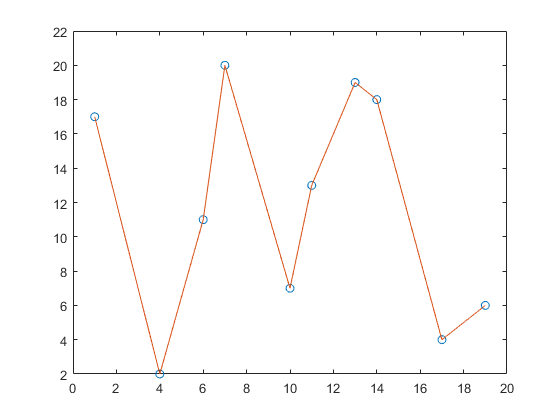

% Ketik jawaban anda di bawah garis
% =================================
x = koordinat(:,1);
xnew = sort(x);
y = koordinat(:,2);
ynew = sort(y);
plot(x,y,"o");
hold on;
n = length(a);
f = @(x) 0;

for i = 1:n
    f = @(x)f(x) + a(i).*x.^(i-1);
    x = xnew;
end
plot(xnew,f(x));
hold off;